# Second Order System

rng(1,'twister');

## Define plant

% define state matrix
A = rand(2);
B = rand(2);
C = rand(2);
D = rand(2);

### Calculate raw plant

% make state space obj
plant = ss(A,B,C,D);
plant.InputName = {'u1','u2'};
plant.OutputName = {'y_1','y_2'};
plant.StateName = {'state_1','state_2'};

open_loop_report_raw = test_plant(plant);

G = tf(plant);

### Calculate augmented plant with state output

Ca = [C;eye(size(C))];
Da = [D;zeros(size(C,1),size(D,2))];
plant_aug = ss(A,B,Ca,Da);
plant_aug.InputName = {'u1','u2'};
plant_aug.OutputName = {'y_1','y_2','x_1','x_2'};
plant_aug.StateName = {'state_1','state_2'};

G_aug = tf(plant_aug);

open_loop_report_aug = test_plant(plant_aug);

## Calculate Controller's

### Calculate LQR controller

Q_provided = diag([10,5]);
R_provided = diag([2,2]);

[K,S,e] = lqr(plant,Q_provided,R_provided,zeros(size(A,1),size(B,1)));

LQR_control = ss(0,zeros(1,2),zeros(2,1),K);
LQR_control.InputName = {'x_1','x_2'};
LQR_control.StateName = {'fake'};
LQR_control.OutputName = {'u1','u2'};

plant_CL = feedback(plant_aug,LQR_control,'name',-1);

G_CL = tf(plant_CL);

closed_loop_report = test_plant(plant_CL);

### How good was LQR

cl_settling_time = [closed_loop_report.stepinfo.SettlingTime]

cl_settling_time =    13.9671   11.3460   11.8474    5.6564   12.6869   16.5834   15.9562    3.6434


ol_settling_time = [open_loop_report_raw.stepinfo.SettlingTime]

ol_settling_time =    NaN   NaN   NaN   NaN


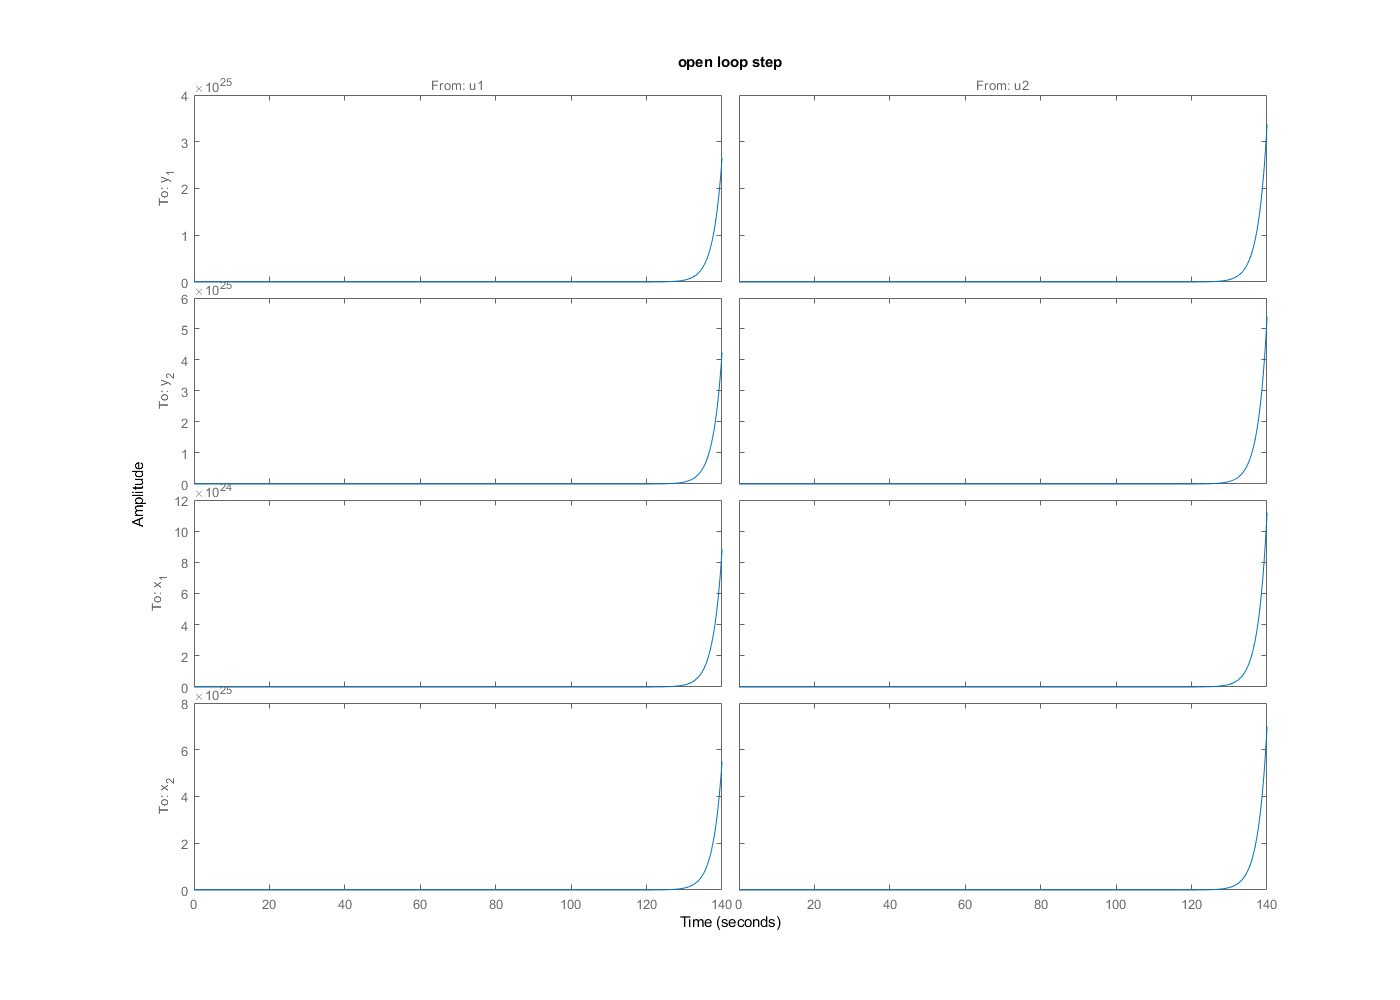


step(plant_aug)
title('open loop step');

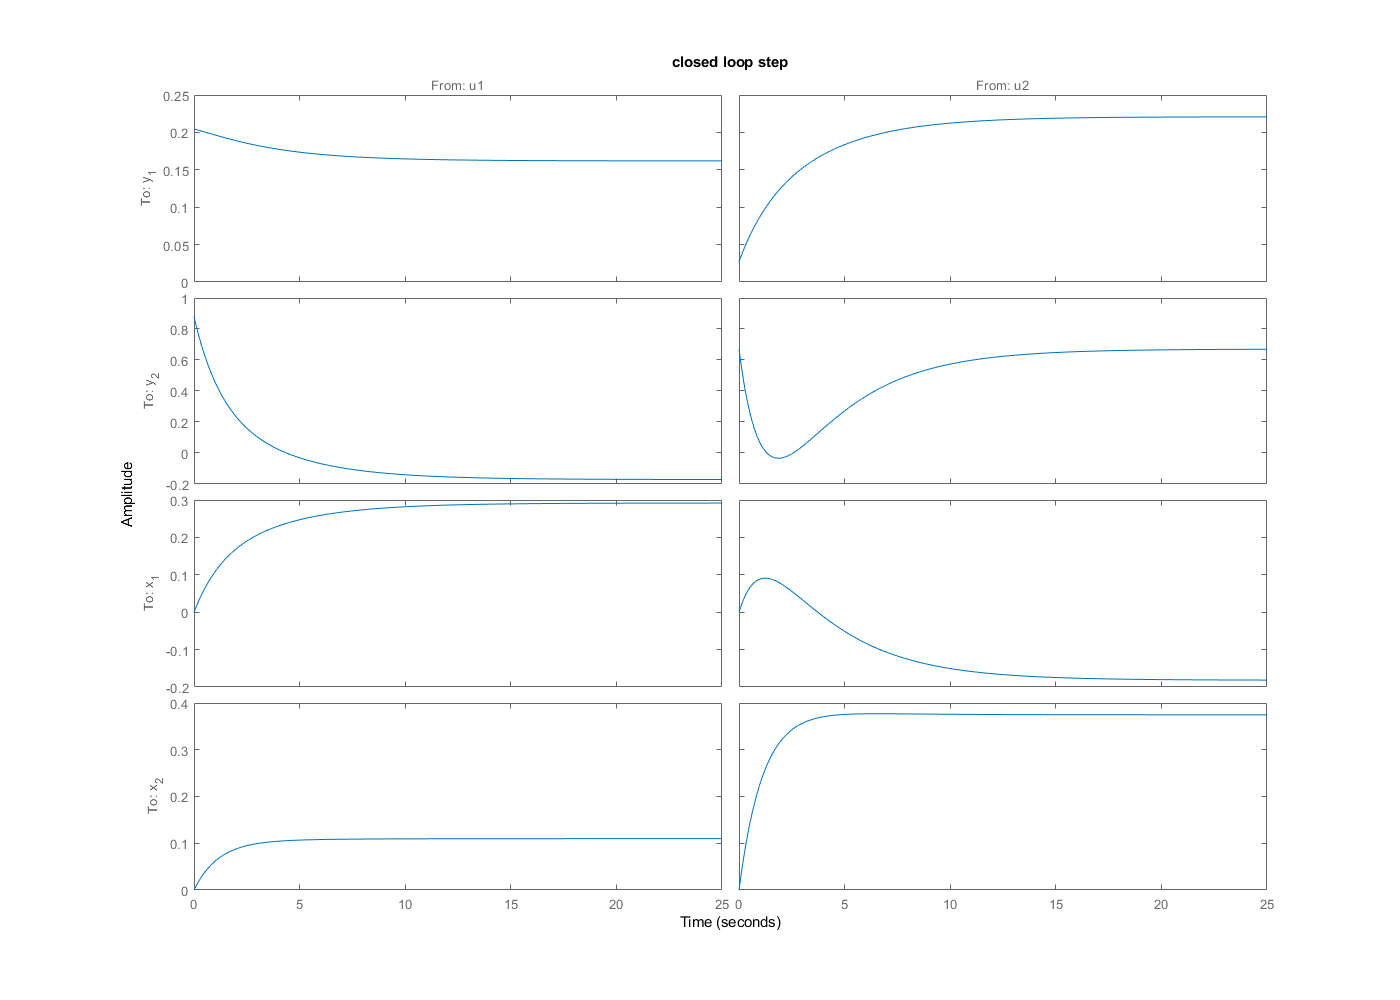

step(plant_CL)
title('closed loop step');

### Calculate Hinf controller

%general plant form
% does not work. https://www.mathworks.com/help/control/ref/genss.html


[K_inf_OL,~,gamma_ol] = hinfsyn(tf(G),2,2)


K_inf_OL =

     []



gamma_ol = Inf


[K_inf_CL,~,gamma_cl] = hinfsyn(tf(G_CL),2,2)


K_inf_CL =
 
  A = 
             x1        x2        x3        x4
   x1    -1.189   -0.7207      1.12     1.267
   x2    0.4384  -0.06379  -0.07626   0.04164
   x3    0.7361    0.9287    -1.256    -2.115
   x4   0.03166    0.0328    0.5392  -0.02141
 
  B = 
               u1          u2
   x1    0.006574  -0.0004898
   x2      0.4248   -0.008278
   x3    -0.01079   0.0004102
   x4     -0.2184    0.004251
 
  C = 
             x1        x2        x3        x4
   y1  -0.01102   -0.2016     1.121     1.266
   y2    0.7346    0.9271   -0.0808    -1.596
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



gamma_cl = 0

s = zpk('s');
W1 = 0.1*(s+100)/(100*s+1); 
W2 = 0.1; 
W3 = [];
P = augw(G_CL,W1,W2,W3)


P =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1       -0.01           0           0           0    0.002316    0.006898    -0.02396
   x2           0       -0.01           0           0       0.182        0.17      0.3363
   x3           0           0       -0.01           0    -0.04586    -0.04727     -0.0582
   x4           0           0           0       -0.01    -0.02885    -0.01778      -0.108
   x5           0           0           0           0      -1.177     -0.5182           0
   x6           0           0           0           0         0.5           0           0
   x7           0           0           0           0           0           0      -1.177
   x8           0           0           0           0           0           0         0.5
 
               x8
   x1    -0.03134
   x2  -1.065e-05
   x3     0.02945
   x4    -0.06066
   x5           0
   x6           0
   x7     -0.5182
   x8           0
 
  B = 
   

[K,CL,gamma] = hinfsyn(P,2,2)


K =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1    -0.02003     0.04386     -0.0444   -0.002341     -0.0245   -0.003738     -0.1594
   x2    -0.05198    -0.04601     -0.0326     -0.0575     0.06769     0.07325     0.06521
   x3  -1.341e-17  -2.184e-17       -0.01   4.338e-17  -9.793e-17  -2.257e-17  -6.438e-16
   x4   3.264e-19   5.391e-19    5.43e-19       -0.01   3.659e-18   2.138e-19   1.401e-17
   x5      0.2163     -0.8678      0.7939     -0.0164       -1.47      -1.019      0.8146
   x6  -8.469e-20   5.553e-20   1.183e-19  -8.998e-21         0.5  -1.483e-18  -2.375e-18
   x7    -0.04088       1.315     -0.8832       0.291      0.9823       1.185      -0.958
   x8  -8.477e-20   7.292e-21   5.435e-20   6.161e-20  -1.298e-18  -1.145e-18         0.5
 
               x8
   x1     -0.1267
   x2    -0.06644
   x3  -5.037e-16
   x4   1.364e-17
   x5       1.505
   x6   4.665e-19
   x7       -2.29
   x8  -4.414e-19
 
  B = 
   

gamma = 10.1090

disp('-----')

-----


### Mixed Sensitivity loop shaping

W1 = ss([0.02,0;0,0.02]);  W1.u = {'e_1','e_2'};  W1.y = {'z1_1','z1_2'}


W1 =
 
  D = 
          e_1   e_2
   z1_1  0.02     0
   z1_2     0  0.02
 
Static gain.



W2 = ss([0.10,0;0,0.10]);  W2.u = {'u1','u2'};   W2.y = {'z2_1','z2_2'}


W2 =
 
  D = 
          u1   u2
   z2_1  0.1    0
   z2_2    0  0.1
 
Static gain.



W3 = ss([0.20,0;0,0.20]);  W3.u = {'y_1','y_2'};   W3.y = {'z3_1','z3_2'}


W3 =
 
  D = 
         y_1  y_2
   z3_1  0.2    0
   z3_2    0  0.2
 
Static gain.



sdmeas  = sumblk('e_1 = w1-y_1');
abmeas = sumblk('e_2 = w2-y_2');

ICinputs = {'w1';'w2';'u1';'u2'};
ICoutputs = {'y_1';'y_2';'z1_1';'z1_2';'z2_1';'z2_2';'z3_1';'z3_2'};

full_sys = connect(G,W1,W2,W3,...
                 sdmeas,abmeas,ICinputs,ICoutputs);

size(full_sys)

State-space model with 8 outputs, 4 inputs, and 4 states.



P = augw(G,W1,W2,W3);
size(P)

State-space model with 8 outputs, 4 inputs, and 4 states.


## Utility Functions

### Evaluate plant

function report = test_plant(plant)

report.stepinfo = stepinfo(plant);
try
    report.HistSettlingTime = histogram(report.stepinfo.SettlingTime);
catch ME
    report.HistSettlingTime = ME.message;
end
report.nyquistPlot = nyquist(plant);
[p,z]=pzmap(plant);
report.systemPoles = p;
report.systemZeros = z;

end